N = 100;
T_0 = [sqrt(2)/2,0,-sqrt(2)/2,0;
       0,1,0,1/2;
       sqrt(2)/2,0,sqrt(2)/2,0;
       0,0,0,1];
delta_t = 0.01;
M = 20;

T_all = simulation_kinematics(T_0,N,delta_t);
p = measurable_points(M);
y = measurement(T_all,M,p);

T_est = Kalman_filter(y,T_0,delta_t,p);

e = zeros(N + 1,1);
time = delta_t*((1:1:N + 1) - 1)';

for i = 1:N + 1
    e(i) = sqrt(sum(sum((T_all(:,:,i) - T_est(:,:,i)).^2)));
end

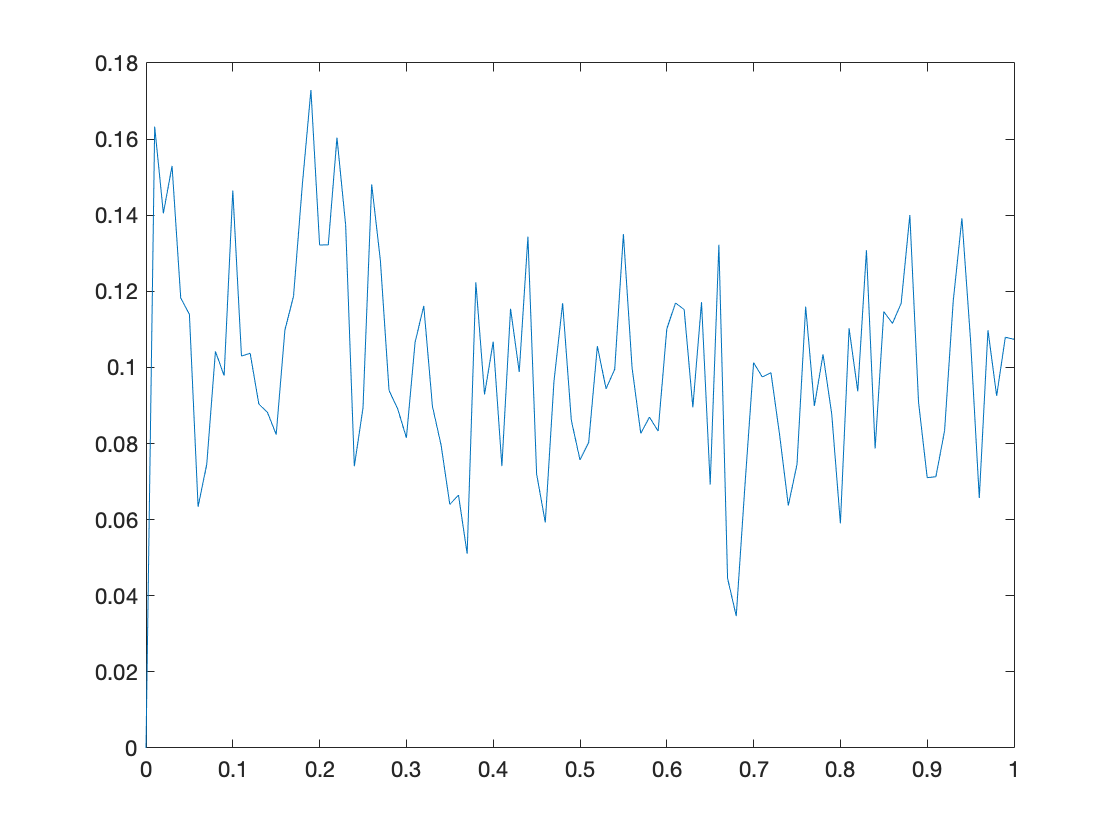

plot(time,e);

csvwrite('Kalman.csv',e);